# **Algorithms for SEM-EDS Mineral Dust Classification**

This is a test script / tutorial for the EDS Classification repository of functions. Written using MATLAB R2022a.

## Mineral Classification

The `eds_classification` function has four algorithms built into it for classifying the mineralogical compositions of dust particles from energy dispersive spectrometry (EDS) data.

#### Load an example dataset

load eds_mineral_net_intensities.mat
data

data = 731×19 table
    Mineral      C         N           O           F        Na        Mg       Al       Si        P         S         Cl        K        Ca       Ti      Cr      Mn      Fe      Co 
    _______    ______    ______    __________    ______    _____    ______    _____    _____    ______    ______    ______    ______    _____    ____    ____    ____    ____

The table `data` contains 731 mineral dust observations. The true class of each mineral is given in the `Mineral` column. The remaining columns contain net intensity data for various elements collected via EDS.

#### Compare true classes to algorithmic classifications

The `weber_classification` algorithm is the default classification algorithm in the `eds_classification` function.

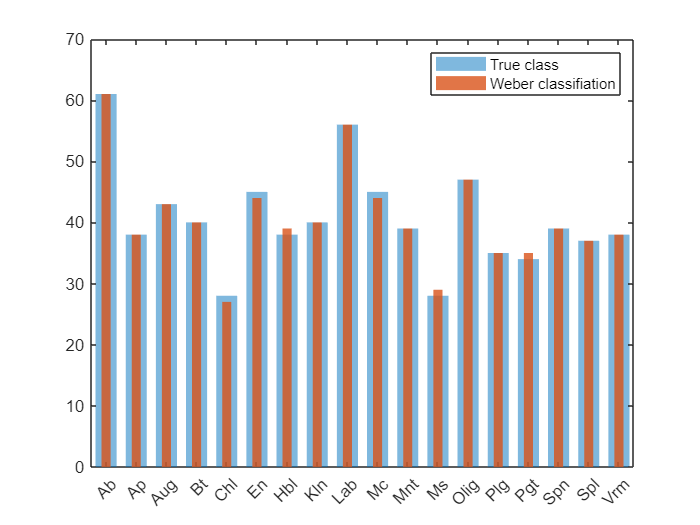

weber = eds_classification(data);

% Visualize results
trueClass = data.Mineral;
histogram(trueClass,'BarWidth',0.7,'FaceAlpha',0.5,'EdgeColor','none')
hold on
  histogram(weber,'BarWidth',0.3,'FaceAlpha',0.8,'EdgeColor','none')
hold off
legend('True class','Weber classifiation')

#### Print the classificaiton accuracy

correct = weber == trueClass;
accuracy = sum(correct)/length(correct).*100;
fprintf('The accuracy of the Weber classification model is %0.1f%% (N=%d).',accuracy,length(weber))

The accuracy of the Weber classification model is 99.5% (N=731).

#### Using the `weber_classification` algorithm directly

Additional outputs can be obtained by calling the `weber_classification` directly. Specify the `groups` output argument to categorize the mineral data into broad mineral groups, and/or specify the `scores` output to produce a probability table showing the likelihood of each classification.

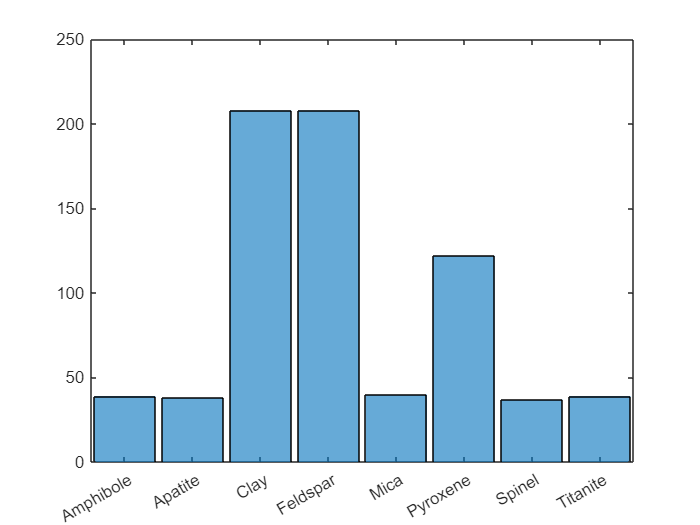

[~,groups,scores] = weber_classification(data);

% Visualize groups
histogram(groups)

% Display the first 50 probability scores
disp(scores(1:50,:))

      Ab       Ap    Aug    Bt    Chl    En    Hbl    Kln    Lab    Mc      Mnt       Ms      Olig      Pgt    Plg    Spl    Spn    Vrm
    _______    __    ___    __    ___    __    ___    ___    ___    __    ________    __    ________    ___    ___    ___    ___    ___
          1    0      0     0      0     0      0      0      0     0            0    0            0     0      0   

### Alternative algorithms

The `eds_classification` function also contains 3 additional algorithms that have been transcribed from the peer-reviewed literature into MATLAB code. Each of these algorithms requires a different combination of elements and is only trained to recognize certain minerals, and so it is recommended that the user see the `help` for each of the algorithms individually to know how to use them properly. However, the *best* way to perform mineral classification is compare the results of multiple techniques, which can you can do easily with the `eds_classification` function or with the algorithms' standalone functions.

load example_mineral_EDS_data.mat % EDS net intensity and atom percent data for 18 unique minerals

%The Donarummo algorithm (Donarummo et al., 2003) 
% [requires EDS net intensity data].
donarummo = eds_classification(net,Algorithm="Donarummo");

%The Kandler algorithm from Kandler et al., 2011)
% [requires EDS atom percent data].
kandler = eds_classification(atPct,Algorithm="Kandler");

%The Panta algorithm (Panta et al., 2023)
% [requires EDS atom percent data].
panta = eds_classification(atPct,Algorithm="Panta");

%Combine the results into a table for comparison
trueClass = net.TrueClass;
results = array2table([trueClass donarummo kandler.class panta],...
    'VariableNames',{'TrueClass','Donarummo','Kandler','Panta'})

results = 18×4 table
    TrueClass        Donarummo         Kandler                  Panta             
    _________    _________________    __________    ______________________________
      Ab         Albite               silicates     Mica-like                     
      Ap         Hectorite            phosphates    Apatite-like                  
      Aug        U-C1                 silicates     Ca-rich silicate/Ca-Si-mixture
      Bt         U-D5                 silicates     Feldspar-like                 
      Chl        Chlorite             silicates     Chlorite-like                 
      En         Hectorite            silicates     Unknown                       
      Hbl        Augite               silicates     Unknown                       
      Kln        Kaolinite            silicates     Kaolinite-like                
      Lab    

The results above demonstrate the importance of using multiple algorithms before finalizing your mineral classifications. This is because each algorithm is limited in its ability to classify certain minerals or mineral groups.

## EDS Spectrum Visualization

Another way to determine the mineralogy of sample is to visualize its EDS spectrum.  Most EDS software applications save the spectral data in files with a `.msa` extension, which can not always be read directly into MATLAB. The `read_msa` function is designed to hasten the process of importing your EDS spectral data.

file1 = 'file1.msa';
spectrum = read_msa(file1);
head(spectrum,5)

ans = 5×2 table
     keV      Counts
    ______    ______
    0.0017     3098 
    0.0067     2988 
    0.0117     2736 
    0.0167     2517 
    0.0217     2111 

### Plotting an EDS x-ray energy spectrum

Use the `xray_plot` function to visualize the x-ray energy data, and use  `xray_peak_label` to label the characteristic x-rays.

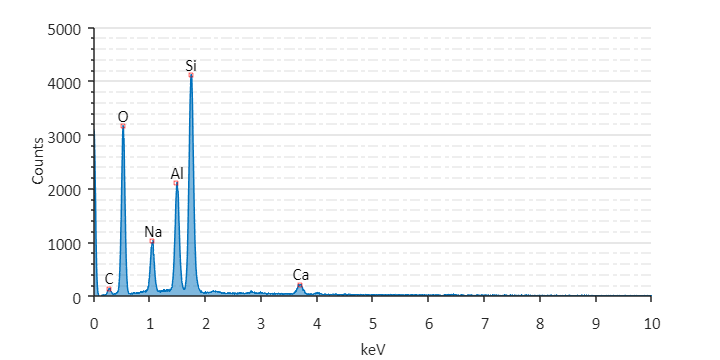

plt = xray_plot(spectrum); % Alternatively: plt = xray_plot('file1.msa');
xray_peak_label(plt)